# **SECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Stochastic Life Cycle Model.

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} \mathbb{E}_0\left(U\right) =  \mathbb{E}_0\left[\sum_{t=1}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma}\right] \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$ and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. You will gradually extend, solve, and simulate this model. When simulating the model, initialize the state variables, including age: for the endogenous state variables, assume equal probabilities for each state; for any exogenous Markov process, draw from the stationary distribution. In each simulation, you must have a panel of 1000 consumers over 30 periods. 

## Recursive Formulation.

The recursive formulation  is


$$V_t(k_t,A_t) = \underset{c_t, n_t, k_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. } A_tk_t^{\alpha}n_t^{1-\alpha} =  c_t + k_{t+1} - (1-\delta)k_t\end{array} \ \text{for} \ t = 1, 2, ... \ ,$$



$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  \\
1 = n_t + l_t.$$


The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t) = \underset{a_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \beta \left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


which reduces the choice space to $a_{t+1}$.

## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\mmhie\Downloads\Required CSV'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\mmhie\Downloads\Required CSV 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = solve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 0.5469 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a population with heterogeneous age.

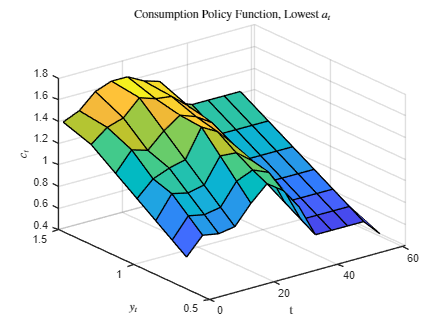

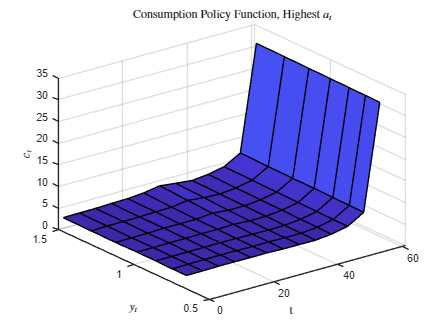

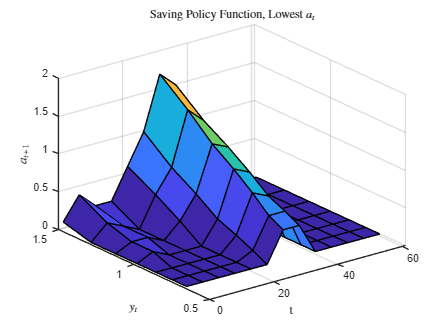

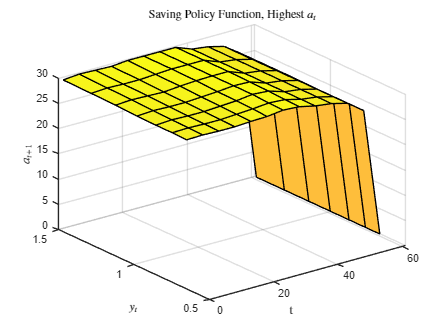

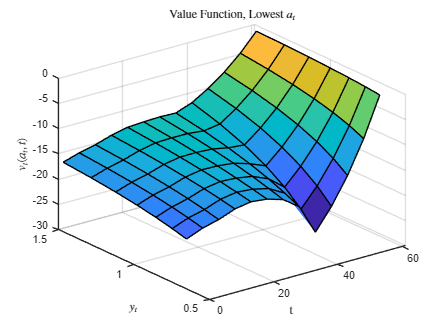

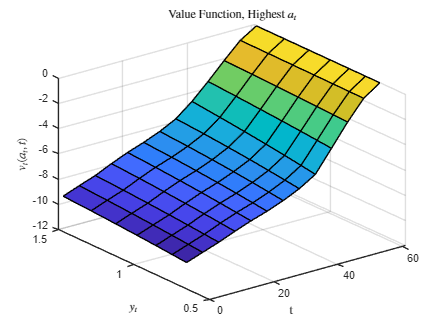

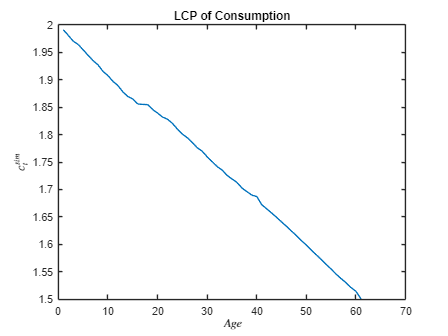

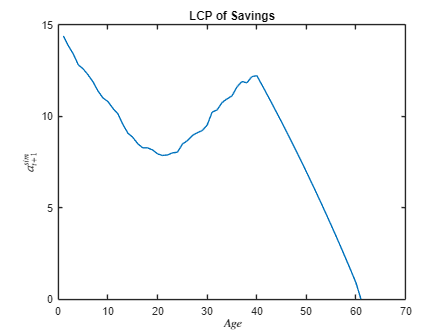

sim = simulate.lc(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.

### Test for multiples $\beta$ and $\gamma$

% Set different values of beta and gamma for the simulations
beta_vals = [0.90, 0.92, 0.94, 0.96];
gamma_vals = [2.00, 3.00, 4.00, 5.00];

% 1. Simulate for γ = 2.00 and β = {0.90, 0.92, 0.94, 0.96}
figure;
colors = lines(length(beta_vals));

% Initialize storage for all lines
cons_data = nan(length(beta_vals), 100); % Assuming T ≤ 100
asset_data = nan(length(beta_vals), 100);
T_max = 0;

for i = 1:length(beta_vals)
    par = model.setup;
    par = model.gen_grids(par); 
    par.beta = beta_vals(i);
    par.gamma = 2.00;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    % Initialize storage
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    % Store data for plotting
    cons_data(i,1:par.T) = lcp_c;
    asset_data(i,1:par.T) = lcp_a;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


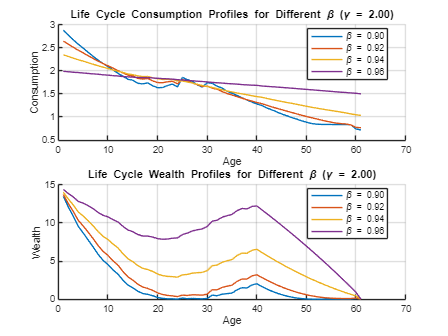


%% Subplot 1: Consumption
subplot(2,1,1);
hold on;
for i = 1:length(beta_vals)
    plot(1:T_max, cons_data(i,1:T_max), 'Color', colors(i,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\beta = %.2f', beta_vals(i)));
end
xlabel('Age');
ylabel('Consumption');
title('Life Cycle Consumption Profiles for Different \beta (\gamma = 2.00)');
legend('show', 'Location', 'best');
grid on;
hold off;

%% Subplot 2: Wealth
subplot(2,1,2);
hold on;
for i = 1:length(beta_vals)
    plot(1:T_max, asset_data(i,1:T_max), 'Color', colors(i,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\beta = %.2f', beta_vals(i)));
end
xlabel('Age');
ylabel('Wealth');
title('Life Cycle Wealth Profiles for Different \beta (\gamma = 2.00)');
legend('show', 'Location', 'best');
grid on;
hold off;


% 2. Simulate for different values of γ = {2.00, 3.00, 4.00, 5.00} and β = 0.96
% Create figure with 2 subplots
figure;
colors = lines(length(gamma_vals));

% Storage for max age
T_max = 0;
cons_data = nan(length(gamma_vals), 100); % Assuming max T ≤ 100
asset_data = nan(length(gamma_vals), 100);

for j = 1:length(gamma_vals)
    par = model.setup;
    par = model.gen_grids(par); 
    par.sigma = gamma_vals(j);
    par.beta = 0.96;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        indices = (sim.tsim == t);
        lcp_c(t) = mean(sim.csim(indices), 'omitnan');
        lcp_a(t) = mean(sim.asim(indices), 'omitnan');
    end

    cons_data(j,1:par.T) = lcp_c;
    asset_data(j,1:par.T) = lcp_a;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


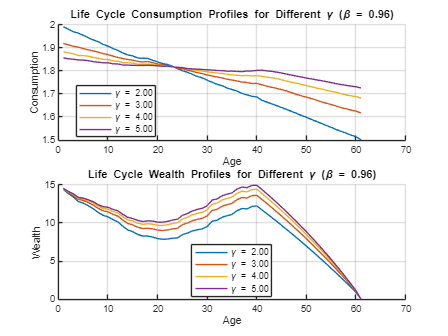


%% Subplot 1: Consumption
subplot(2,1,1);
hold on;
for j = 1:length(gamma_vals)
    plot(1:T_max, cons_data(j,1:T_max), 'Color', colors(j,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f', gamma_vals(j)));
end
xlabel('Age');
ylabel('Consumption');
title('Life Cycle Consumption Profiles for Different \gamma (\beta = 0.96)');
legend('show', 'Location', 'best');
grid on;
hold off;

%% Subplot 2: Wealth
subplot(2,1,2);
hold on;
for j = 1:length(gamma_vals)
    plot(1:T_max, asset_data(j,1:T_max), 'Color', colors(j,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f', gamma_vals(j)));
end
xlabel('Age');
ylabel('Wealth');
title('Life Cycle Wealth Profiles for Different \gamma (\beta = 0.96)');
legend('show', 'Location', 'best');
grid on;
hold off;



% 3. Compute average simulated wealth for different combinations of γ and β and plot a heatmap
avg_wealth = zeros(length(gamma_vals), length(beta_vals));  % Matrix to store average wealth

for i = 1:length(gamma_vals)
    for j = 1:length(beta_vals)
        par.sigma = gamma_vals(i);
        par.beta = beta_vals(j);

        % Solve and simulate the model
        sol = solve.lc(par);  % Solve the model
        sim = simulate.lc(par, sol);  % Simulate the model
        
        % Calculate the average wealth across all individuals and time periods
        avg_wealth(i, j) = mean(sim.asim, 'all');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.

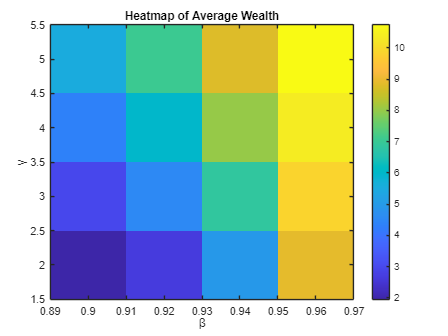


% Plot the heatmap
figure;
imagesc(beta_vals, gamma_vals, avg_wealth);
colorbar;
xlabel('β');
ylabel('γ');
title('Heatmap of Average Wealth');
set(gca, 'YDir', 'normal');

%% Define parameter values
beta_vals = [0.90, 0.92, 0.94, 0.96];
gamma_vals = [2.00, 3.00, 4.00, 5.00];

% Initialize storage for all data
cons_data = nan(length(beta_vals), 100);  % Assuming T_max ≤ 100
asset_data = nan(length(beta_vals), 100);
T_max = 0;

% Initialize structure for storing descriptive statistics
descriptive_stats = struct();

%% Loop over different betas to calculate consumption and wealth
for i = 1:length(beta_vals)
    par = model.setup;
    par = model.gen_grids(par); 
    par.beta = beta_vals(i);
    par.gamma = 2.00;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    cons_data(i,1:par.T) = lcp_c;
    asset_data(i,1:par.T) = lcp_a;

    % Calculate descriptive statistics for consumption
    cons_mean = mean(cons_data(i, 1:T_max), 'omitnan');
    cons_std = std(cons_data(i, 1:T_max), 'omitnan');
    cons_min = min(cons_data(i, 1:T_max), [], 'omitnan');
    cons_max = max(cons_data(i, 1:T_max), [], 'omitnan');
    cons_median = median(cons_data(i, 1:T_max), 'omitnan');

    % Store statistics for consumption
    descriptive_stats.beta_vals(i).cons_mean = cons_mean;
    descriptive_stats.beta_vals(i).cons_std = cons_std;
    descriptive_stats.beta_vals(i).cons_min = cons_min;
    descriptive_stats.beta_vals(i).cons_max = cons_max;
    descriptive_stats.beta_vals(i).cons_median = cons_median;

    % Calculate descriptive statistics for wealth
    wealth_mean = mean(asset_data(i, 1:T_max), 'omitnan');
    wealth_std = std(asset_data(i, 1:T_max), 'omitnan');
    wealth_min = min(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_max = max(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_median = median(asset_data(i, 1:T_max), 'omitnan');

    % Store statistics for wealth
    descriptive_stats.beta_vals(i).wealth_mean = wealth_mean;
    descriptive_stats.beta_vals(i).wealth_std = wealth_std;
    descriptive_stats.beta_vals(i).wealth_min = wealth_min;
    descriptive_stats.beta_vals(i).wealth_max = wealth_max;
    descriptive_stats.beta_vals(i).wealth_median = wealth_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------




%% Display Descriptive Statistics for Consumption
cons_table = table();
cons_table.Beta = beta_vals';
cons_table.Mean = [descriptive_stats.beta_vals(:).cons_mean]';
cons_table.StdDev = [descriptive_stats.beta_vals(:).cons_std]';
cons_table.Min = [descriptive_stats.beta_vals(:).cons_min]';
cons_table.Max = [descriptive_stats.beta_vals(:).cons_max]';
cons_table.Median = [descriptive_stats.beta_vals(:).cons_median]';

disp('--- Descriptive Statistics for Consumption with Different Beta Values ---');

--- Descriptive Statistics for Consumption with Different Beta Values ---



disp(cons_table);

    Beta     Mean     StdDev       Min       Max      Median
    ____    ______    _______    _______    ______    ______

     0.9    1.5459    0.55875    0.71627    2.8804    1.6381
    0.92    1.5669    0.50794    0.76649    2.6465    1.6246
    0.94    1.6334    0.37153     1.0341    2.3483    1.6412
    0.96    1.7482     0.1403     1.5007    1.9908    1.7506




%% Loop over different gammas to calculate consumption and wealth
cons_data = nan(length(gamma_vals), 100);  % Reset storage for consumption data
asset_data = nan(length(gamma_vals), 100);  % Reset storage for asset data
T_max = 0;

for j = 1:length(gamma_vals)
    par = model.setup;
    par = model.gen_grids(par); 
    par.gamma = gamma_vals(j);
    par.beta = 0.96;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        indices = (sim.tsim == t);
        lcp_c(t) = mean(sim.csim(indices), 'omitnan');
        lcp_a(t) = mean(sim.asim(indices), 'omitnan');
    end

    cons_data(j,1:par.T) = lcp_c;
    asset_data(j,1:par.T) = lcp_a;

    % Calculate descriptive statistics for consumption
    cons_mean = mean(cons_data(j, 1:T_max), 'omitnan');
    cons_std = std(cons_data(j, 1:T_max), 'omitnan');
    cons_min = min(cons_data(j, 1:T_max), [], 'omitnan');
    cons_max = max(cons_data(j, 1:T_max), [], 'omitnan');
    cons_median = median(cons_data(j, 1:T_max), 'omitnan');

    % Store statistics for consumption
    descriptive_stats.gamma_vals(j).cons_mean = cons_mean;
    descriptive_stats.gamma_vals(j).cons_std = cons_std;
    descriptive_stats.gamma_vals(j).cons_min = cons_min;
    descriptive_stats.gamma_vals(j).cons_max = cons_max;
    descriptive_stats.gamma_vals(j).cons_median = cons_median;

    % Calculate descriptive statistics for wealth
    wealth_mean = mean(asset_data(j, 1:T_max), 'omitnan');
    wealth_std = std(asset_data(j, 1:T_max), 'omitnan');
    wealth_min = min(asset_data(j, 1:T_max), [], 'omitnan');
    wealth_max = max(asset_data(j, 1:T_max), [], 'omitnan');
    wealth_median = median(asset_data(j, 1:T_max), 'omitnan');

    % Store statistics for wealth
    descriptive_stats.gamma_vals(j).wealth_mean = wealth_mean;
    descriptive_stats.gamma_vals(j).wealth_std = wealth_std;
    descriptive_stats.gamma_vals(j).wealth_min = wealth_min;
    descriptive_stats.gamma_vals(j).wealth_max = wealth_max;
    descriptive_stats.gamma_vals(j).wealth_median = wealth_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


%% Display Descriptive Statistics for Wealth
wealth_table = table();
wealth_table.Gamma = gamma_vals';
wealth_table.Mean = [descriptive_stats.gamma_vals(:).cons_mean]';
wealth_table.StdDev = [descriptive_stats.gamma_vals(:).cons_std]';
wealth_table.Min = [descriptive_stats.gamma_vals(:).cons_min]';
wealth_table.Max = [descriptive_stats.gamma_vals(:).cons_max]';
wealth_table.Median = [descriptive_stats.gamma_vals(:).cons_median]';

disp('--- Descriptive Statistics for Wealth with Different Gamma Values ---');

--- Descriptive Statistics for Wealth with Different Gamma Values ---


disp(wealth_table);

    Gamma     Mean     StdDev     Min       Max      Median
    _____    ______    ______    ______    ______    ______

      2      1.7482    0.1403    1.5007    1.9908    1.7506
      3      1.7482    0.1403    1.5007    1.9908    1.7506
      4      1.7482    0.1403    1.5007    1.9908    1.7506
      5      1.7482    0.1403    1.5007    1.9908    1.7506




%% Define parameter values
beta_vals = [0.90, 0.92, 0.94, 0.96];
gamma_vals = [2.00, 3.00, 4.00, 5.00];

% Initialize storage for all data
cons_data = nan(length(beta_vals), 100);  % Assuming T_max ≤ 100
asset_data = nan(length(beta_vals), 100);
T_max = 0;

% Initialize structure for storing descriptive statistics
descriptive_stats = struct();

%% Loop over different betas to calculate consumption and wealth
for i = 1:length(beta_vals)
    par = model.setup;
    par = model.gen_grids(par); 
    par.beta = beta_vals(i);
    par.gamma = 2.00;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    cons_data(i,1:par.T) = lcp_c;
    asset_data(i,1:par.T) = lcp_a;

    % Calculate descriptive statistics for consumption
    cons_mean = mean(cons_data(i, 1:T_max), 'omitnan');
    cons_std = std(cons_data(i, 1:T_max), 'omitnan');
    cons_min = min(cons_data(i, 1:T_max), [], 'omitnan');
    cons_max = max(cons_data(i, 1:T_max), [], 'omitnan');
    cons_median = median(cons_data(i, 1:T_max), 'omitnan');

    % Store statistics for consumption
    descriptive_stats.beta_vals(i).cons_mean = cons_mean;
    descriptive_stats.beta_vals(i).cons_std = cons_std;
    descriptive_stats.beta_vals(i).cons_min = cons_min;
    descriptive_stats.beta_vals(i).cons_max = cons_max;
    descriptive_stats.beta_vals(i).cons_median = cons_median;

    % Calculate descriptive statistics for wealth
    wealth_mean = mean(asset_data(i, 1:T_max), 'omitnan');
    wealth_std = std(asset_data(i, 1:T_max), 'omitnan');
    wealth_min = min(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_max = max(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_median = median(asset_data(i, 1:T_max), 'omitnan');

    % Store statistics for wealth
    descriptive_stats.beta_vals(i).wealth_mean = wealth_mean;
    descriptive_stats.beta_vals(i).wealth_std = wealth_std;
    descriptive_stats.beta_vals(i).wealth_min = wealth_min;
    descriptive_stats.beta_vals(i).wealth_max = wealth_max;
    descriptive_stats.beta_vals(i).wealth_median = wealth_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



%% Descriptive statistics for consumption across different gammas
gamma_stats = cell(length(gamma_vals), 5);  % Cell array for statistics: mean, std, min, max, median

for j = 1:length(gamma_vals)
    par = model.setup;
    par = model.gen_grids(par); 
    par.gamma = gamma_vals(j);
    par.beta = 0.96;  % Default beta value
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    lcp_c = nan(par.T,1);
    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
    end

    cons_max = max(lcp_c, [], 'omitnan');
    cons_median = median(lcp_c, 'omitnan');

    gamma_stats{j, 1} = gamma_vals(j);
    gamma_stats{j, 2} = cons_mean;
    % Calculate descriptive statistics for consumption for current gamma
    cons_mean = mean(lcp_c, 'omitnan');
    cons_std = std(lcp_c, 'omitnan');
    cons_min = min(lcp_c, [], 'omitnan');
    gamma_stats{j, 3} = cons_std;
    gamma_stats{j, 4} = cons_min;
    gamma_stats{j, 5} = cons_max;
    gamma_stats{j, 6} = cons_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



% Display gamma stats table for consumption
stat3 = cell2table(gamma_stats, 'VariableNames', {'Gamma', 'Mean', 'Std', 'Min', 'Max', 'Median'});
disp('--- Descriptive Statistics for Consumption with Different Gamma Values ---');

--- Descriptive Statistics for Consumption with Different Gamma Values ---


%% Descriptive statistics for wealth across different betas
beta_stats = cell(length(beta_vals), 5);  % Cell array for statistics: mean, std, min, max, median

for i = 1:length(beta_vals)
    par = model.setup;
    par = model.gen_grids(par); 
    par.beta = beta_vals(i);
    par.gamma = 2.00;  % Default gamma value
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    lcp_a = nan(par.T,1);
    for t = 1:par.T
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    % Calculate descriptive statistics for wealth for current beta
    wealth_mean = mean(lcp_a, 'omitnan');
    wealth_std = std(lcp_a, 'omitnan');
    wealth_min = min(lcp_a, [], 'omitnan');
    wealth_max = max(lcp_a, [], 'omitnan');
    wealth_median = median(lcp_a, 'omitnan');

    beta_stats{i, 1} = beta_vals(i);
    beta_stats{i, 2} = wealth_mean;
    beta_stats{i, 3} = wealth_std;
    beta_stats{i, 4} = wealth_min;
    beta_stats{i, 5} = wealth_max;
    beta_stats{i, 6} = wealth_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------




% Display beta stats table for wealth
stat4 = cell2table(beta_stats, 'VariableNames', {'Beta', 'Mean', 'Std', 'Min', 'Max', 'Median'});
disp('--- Descriptive Statistics for Consumption with Different Beta Values ---');

--- Descriptive Statistics for Consumption with Different Beta Values ---
